7.6 Flow Across Banks of Tubes 

Fundamentals of Heat and Mass Transfer, 8th Edition

Table for C and M values

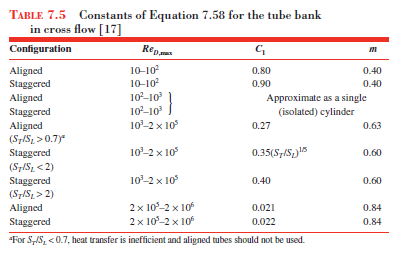

Table for C and M coeffiecents. 

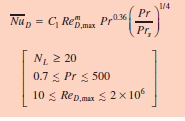

At least 20 tubes(**5 not 20 need correction factor**)

Prandlt number range, Reynolds number range

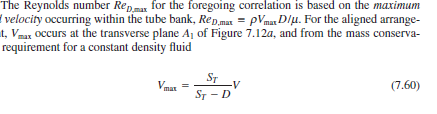

Input vector creation and graphing

AirSpeed = 0:0.1:10;
y = Heatloss(AirSpeed)

ReynoldsNumber = 1.0e+04 *

         0    0.0235    0.0470    0.0705    0.0940    0.1175    0.1410    0.1645    0.1881    0.2116    0.2351    0.2586    0.2821    0.3056    0.3291    0.3526    0.3761    0.3996    0.4231    0.4466    0.4701    0.4936    0.5171    0.5406    0.5642    0.5877    0.6112    0.6347    0.6582    0.6817    0.7052    0.7287    0.7522    0.7757    0.7992    0.8227    0.8462    0.8697    0.8932    0.9167    0.9403    0.9638    0.9873    1.0108    1.0343    1.0578    1.0813    1.1048    1.1283    1.1518


y = 1.0e+03 *

         0    0.2433    0.3688    0.4704    0.5590    0.6391    0.7129    0.7820    0.8473    0.9093    0.9686    1.0256    1.0806    1.1338    1.1853    1.2354    1.2842    1.3318    1.3782    1.4237    1.4682    1.5118    1.5546    1.5966    1.6379    1.6785    1.7185    1.7578    1.7966    1.8348    1.8725    1.9097    1.9465    1.9827    2.0186    2.0540    2.0890    2.1236    2.1579    2.1918    2.2253    2.2585    2.2914    2.3240    2.3563    2.3883    2.4200    2.4514    2.4826    2.5135


hold on
ylabel('HeatLoss[w]');
plot(AirSpeed,y,'.')
%yyaxis right
%plot(z,AirSpeed,'.')
xlabel('AirSpeed at Entrance [m/s]');
%ylabel('Ploss');
var2 = battTemp-273.15;
var1 = tempHigh-273;
title_string = sprintf("AirSpeed Vs Heatloss at Ambient %.2f C and Battery Temp %.2f",var1,var2)

title_string = "AirSpeed Vs Heatloss at Ambient 43.15 C and Battery Temp 53.00"

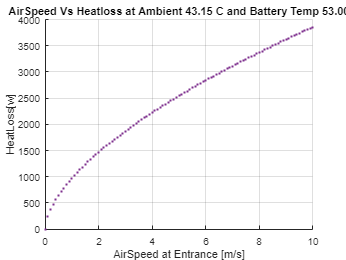

title(title_string)
grid on;
hold off

function HeatLoss = Heatloss(AirSpeed)


Basic

%Reynolds Number Calcs
    BattColumns = 23;
    BatteryRows =7;
    tempLow = 15+ 273.15;
    battTemp = 53+ 273.15;
    tempHigh = 43 + 273.15;
    DiameterCells = 16.4/1000; % CHANGE THIS BECAUSE NO GAP




    dynViscosity = py.CoolProp.CoolProp.PropsSI('V', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    densityAir = py.CoolProp.CoolProp.PropsSI('D', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    thermCond = py.CoolProp.CoolProp.PropsSI('L', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    ConstPNum = py.CoolProp.CoolProp.PropsSI('C', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    KinViscosity = dynViscosity/densityAir;


% Vert vs Horiz Spacing
    St = 31.3/1000;% spacing between columns
    Sl = 34.3/1000;%center spacing in direction of initial airflow
    Vmax =  St.*AirSpeed./(St-DiameterCells);

    ReynoldsNumber =  Vmax * DiameterCells / KinViscosity % WILL have to update C1 and M Manually before IF statements. 
    PrandtlAirLow = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempLow, 'P|not_imposed', 101325, 'air');
    PrandtlAirHigh = py.CoolProp.CoolProp.PropsSI('Prandtl', 'T', tempHigh, 'P|not_imposed', 101325, 'air');

    C1 = 0.35*(St/Sl)^(1/5);
    mVal = 0.6; % Table
    C2 = 0.95; %Table (correction factor for 5)



    NusseltD = C2*C1*ReynoldsNumber.^mVal.*(PrandtlAirLow.^0.36).*(PrandtlAirLow./PrandtlAirHigh).^(0.25);
    Hline = NusseltD*thermCond/DiameterCells;

Adjusted Delta for warming


    insideVarTop = (-pi*DiameterCells*(BattColumns*BatteryRows)*Hline);

    insideVarBot = (densityAir.*AirSpeed.*(BatteryRows)*St*ConstPNum);

    adjDelTso = (battTemp - tempHigh)/(battTemp - tempLow) * exp(insideVarTop/insideVarBot);

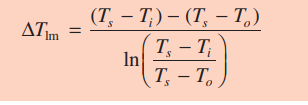

    deltTlm = (battTemp-tempLow)-(adjDelTso)/(log((battTemp-tempLow)/(adjDelTso)));

    qPrime = (BatteryRows*BattColumns)*(Hline*pi*DiameterCells*deltTlm);%in KW per m
    qPrimeLadjust = qPrime*0.065;%Temp dissapated

pressure loss

    Pt = St/DiameterCells;
    Pl = Sl/DiameterCells;
    PTPL = (Pt-1)/(Pl-1);

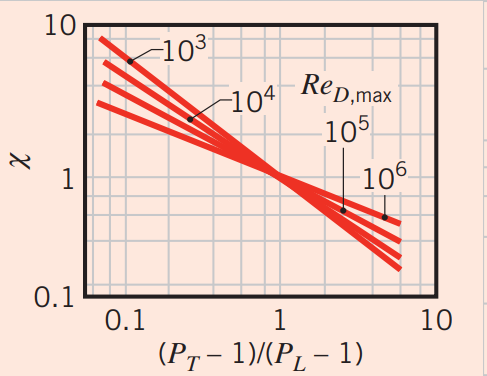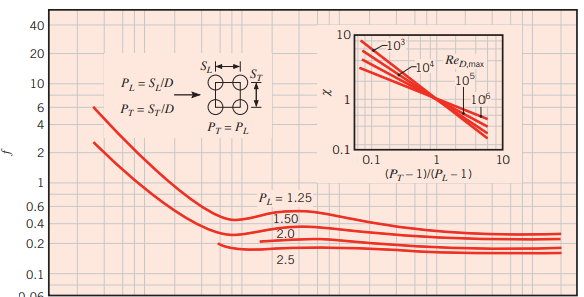

    fancyX = 1.4;
    fricFactor = 0.22;

    deltPLoss = 5.* fancyX .* (densityAir./2.*Vmax.^2) .* fricFactor;

    HeatLoss = qPrimeLadjust;

end